# This script is intended to introduce plotting as the most elementary visualization techinuque of Matlab.

## Data definition

### Creating vectors representing trigonometric functions

Creating abscissa (x) values of the functions:

angle_vect = 0 : 0.05 * 2 * pi

angle_vect = 0

Creating ordinate (y) values of three trigonometric functions:

sine = sin(angle_vect);
sin2 = 2 * sin(0.5 * angle_vect + pi/8);
cosine = 0.5 * cos(2 * angle_vect - pi/8);


## Creating figure (window for visualization) and axis (coordinate sytem)

### Creating figure and setting its properties

figure_object = figure;
figure_object.Name = "Trigonometric functions";
figure_object.Color = "white";
figure_object.Units = "normalized";
figure_object.Position = [0.1, 0.1, 0.8, 0.75];

Consider printing sizes:

width_of_fig = 8; % cm
height_of_fig = 5; % cm

figure_object.PaperUnits = "centimeters"

figure_object =   Figure (1: Trigonometric functions) with properties:

      Number: 1
        Name: 'Trigonometric functions'
       Color: [1 1 1]
    Position: [0.1000 0.1000 0.8000 0.7500]
       Units: 'normalized'

  Show all properties


figure_object.PaperPosition = [0, 0, width_of_fig, height_of_fig];
figure_object.PaperSize = [width_of_fig, height_of_fig]

figure_object =   Figure (1: Trigonometric functions) with properties:

      Number: 1
        Name: 'Trigonometric functions'
       Color: [1 1 1]
    Position: [0.1000 0.1000 0.8000 0.7500]
       Units: 'normalized'

  Show all properties


Other form:

### Creating axis and setting its properties

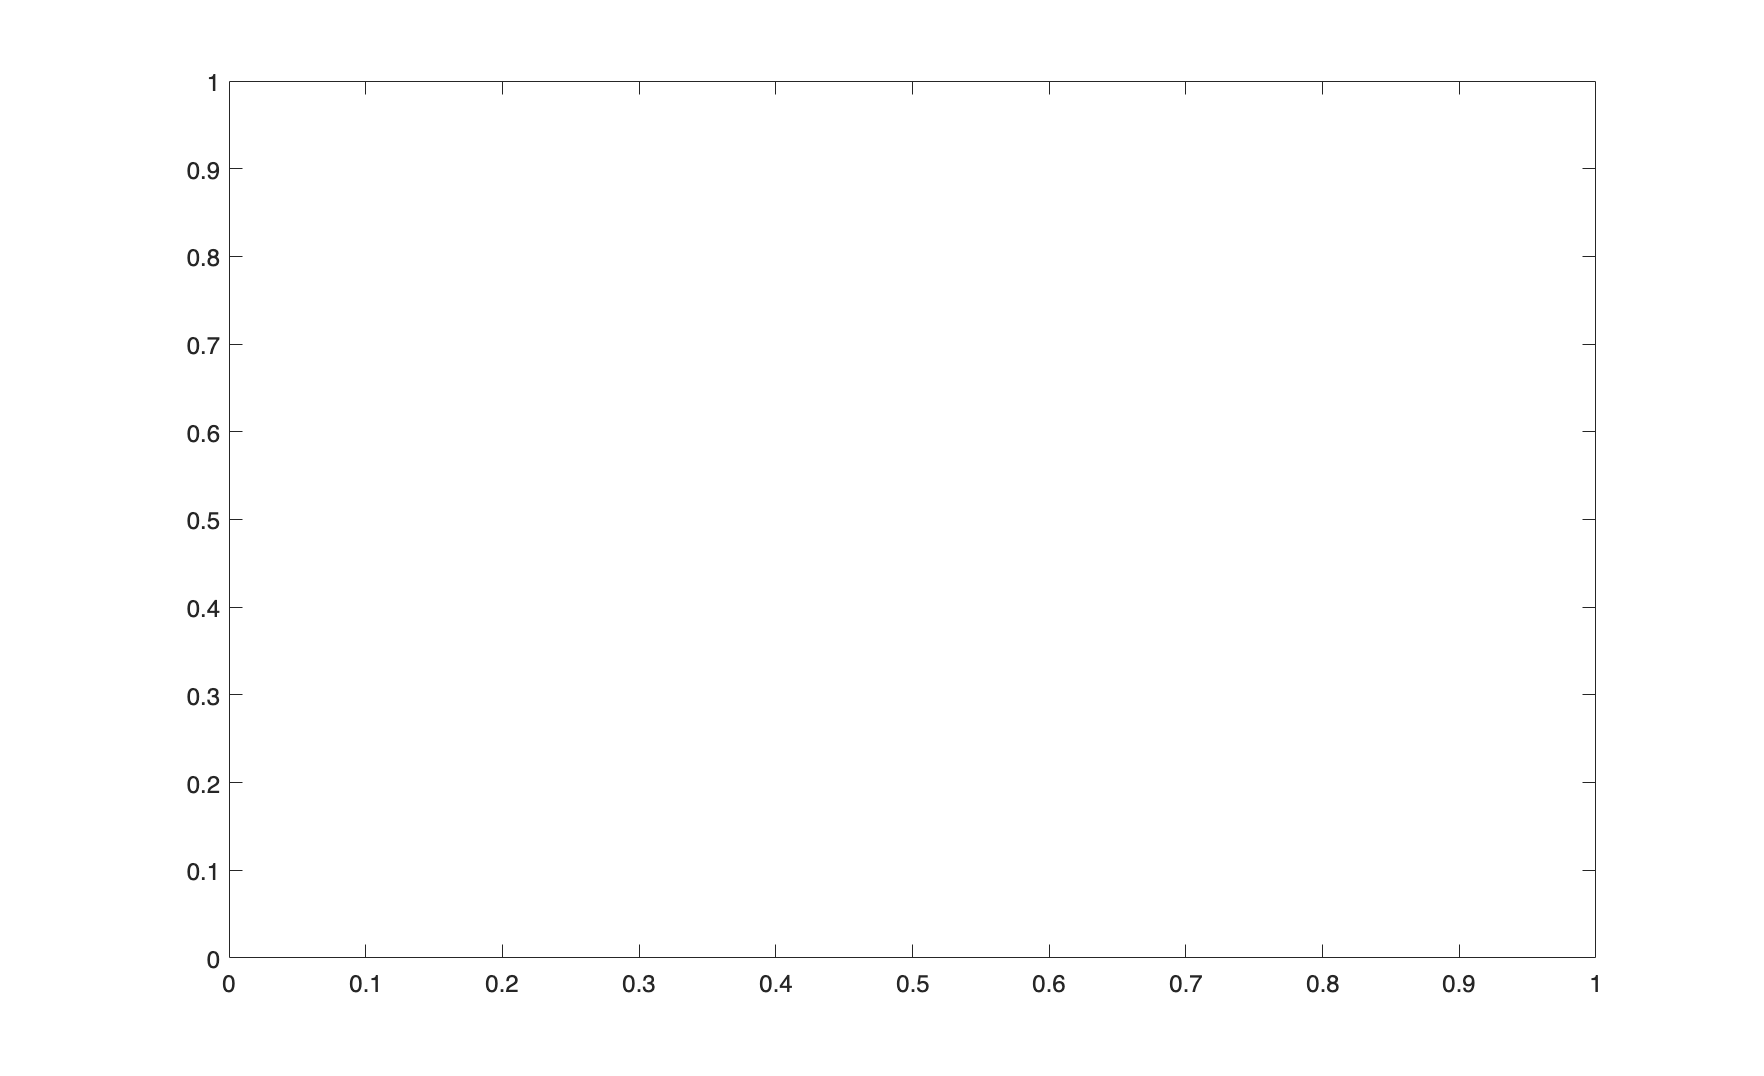

axis_object = axes(figure_object);
axis_object.FontSize = 12;
axis_object.FontWeight = "normal";
axis_object.TitleFontWeight = "bold";
axis_object.TitleFontSizeMultiplier = 1.2;
axis_object.LabelFontSizeMultiplier = 1.0;
axis_object.Units = "normalized";
axis_object.Box = "on";

Other form

## Plotting (2D line visualization)

Holding the axis to plot more than one 'curves'

hold(axis_object,"on");

Plotting sine function over angle with solid blue line, 'o' markers

plot(axis_object, angle_vect, sine2, 'b-o')

Unrecognized function or variable 'sine2'.

Plotting sine function over angle with green '*' markers (without connecting line)

Detailed settings of plot

Release the axis

Put grid on axis because it look nice :)

Labels and title

Setting of axis values and ticks

## Save graphics

### Vector graphics

                      figure                  file name              format        rendering

### Pixel graphics

## Creating subplots

Subplots are useful when one wants to create corresponding plots on different coordinate systems.

Let's create two coordinate systems under each other! Multiple coordinate systems in a given layout can be created with $\texttt{subplot(m,n,p)}$ function, where $\texttt{m}$, $\texttt{n}$ denotes the number of vertically and horizontally aligned axes and $\texttt{p}$ is the index of the current coordinate system.

Creating the first coordinate system (axis) with vertical alignment (2 rows, 1 columns):

Creating the second coordinate system (axis) with vertical alignment (2 rows, 1 columns):

Plot title and labels: